# Pràctica 7. Exercici 4

Exercici 12 del document CN_full4.pdf

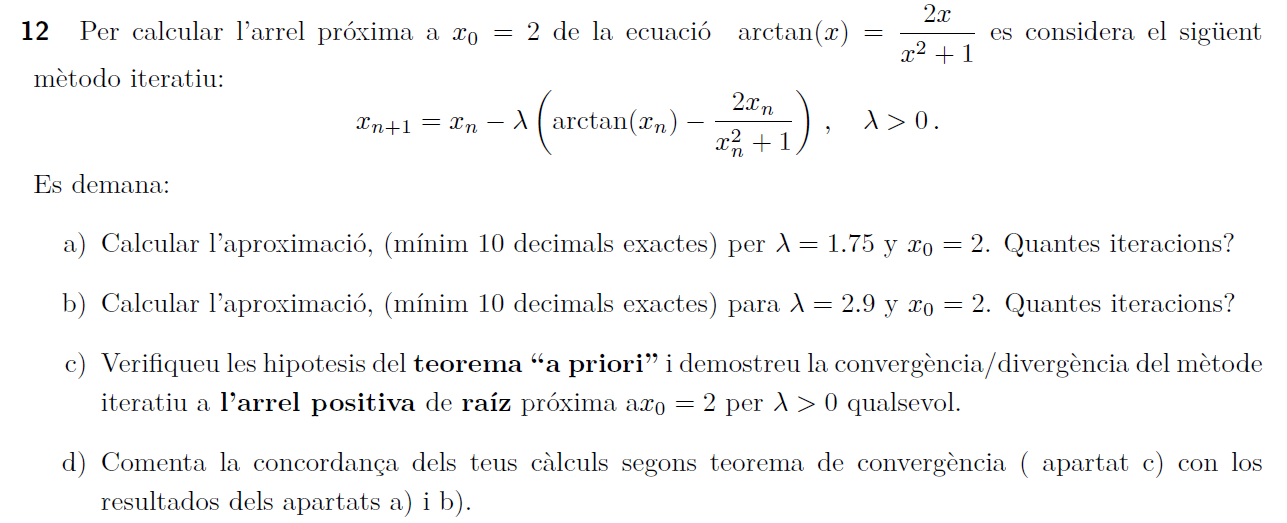

================================================================================

- `Gràfica de `$\arctan(x)=\displaystyle\frac{2x}{x^2+1}$  en `un interval per la solució pròxima a `$x_0=2$.

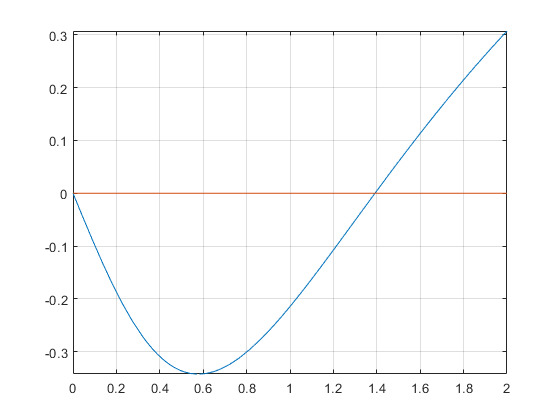

clearvars
syms t
f(t) = atan(t)-2*t/(t^2+1);
fplot([f(t),0],[0,2]),grid

- `Estudieu la convergència del mètode `$x_{n+1}=x_n-\lambda\left( \arctan(x_n)-\frac{2x_n}{x_n^2+1}\right)\,,\quad\lambda>0$ `per la solució pròxima a `$x_0=2$`.`

syms L
g(t,L)=t-L*f(t)

$$g(t, L) = t-L\,\left(\mathrm{atan}\left(t\right)-\frac{2\,t}{t^{2}+1}\right)$$

dg(t,L) = diff(g(t,L),t) 

$$dg(t, L) = L\,\left(\frac{1}{t^{2}+1}-\frac{4\,t^{2}}{{\left(t^{2}+1\right)}^{2}}\right)+1$$

% ESQUEMA
% g'(x) = 1 - Lf'(x), T.convergencia |g'|<1, -1 < 1- Lf'(x) < 1, 
% L = 1/f'(x), -2 = -Lf'(x), L = 2/f'(x)
df(t) = diff( f(t));
lmax = double(2/df(2))   % valors admisibles per lambda = (0,2/f'(alpha))

lmax =        4.5455


l = double(1/df(1.3917))

l =         1.793


l = double(2/df(1.3917))

l =        3.5859


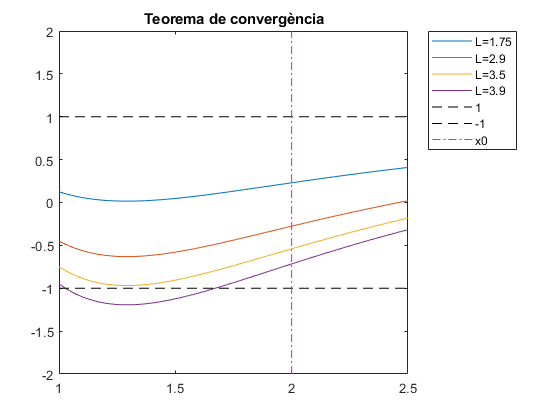

fplot([dg(t,1.75),dg(t,2.9),dg(t,3.5),dg(t,3.9)],[1,2.5])
legend('L=1.75','L=2.9','L=3.5','L=3.9','Location','bestoutside')
hold on
fplot(@(x)ones(size(x)),[1,2.5],'k','LineStyle','--','DisplayName','1')
fplot(@(x)-ones(size(x)),[1,2.5],'k','LineStyle','--','DisplayName','-1')
line([2,2],[-2,2],'Color','m','LineStyle','-.','DisplayName','x0')
hold off
title('Teorema de convergència')

- `Calcular l'aproximació, `$x_n \approx\alpha$` (mínim 10 decimals exactes) per `$$\lambda = 1.75$$` i `$$x_0=2$$`. Quantes iteracions?  `

x = 2;
n = 0;
control = 1;
f(t) = atan(t)-2*t/(t^2+1);
g(t,L) = t-L*(atan(t)-2*t/(t^2+1));
while (n < 50 && control > 0.5e-10)
    n = n+1;
    y = double(g(x,1.75));
    control = max(abs(y-x),abs(f(y)));
    x = y;
end
Y1 = double(y)

Y1 =        1.3917


tolf = double(f(Y1))

tolf =    2.2922e-13


fprintf('El mètode convergeix en n = %d iteracions al valor x = %g\n',n,x)

El mètode convergeix en n = 8 iteracions al valor x = 1.39175


- `Calcular l'aproximació, `$x_n \approx\alpha$` (mínim 10 decimals exactes) per `$$\lambda = 2.9$$` i `$$x_0=2$$`. Quantes iteracions?  `

k = double(dg(2,2.9))

k =        -0.276


x = 2;
n = 0;
control = 1;
f(t) = atan(t)-2*t/(t^2+1);
g(t,L)=t-L*(atan(t)-2*t/(t^2+1));
while(n < 50 && control > 0.5e-10)
    n=n+1;
    y = double(g(x,2.9));
    control = max(abs(y-x),abs(f(y)));
    x = y;
end
Y2 = double(y), n

Y2 =        1.3917


n =     50


tolf = double(f(Y2))

tolf =    8.2082e-12


fprintf('El mètode convergeix en n = %d iteracions al valor x = %g\n',n,x)

El mètode convergeix en n = 50 iteracions al valor x = 1.39175


- `Quin mètode és convergent? Quin és divergent? Verifica la concordança dels resultats obtinguts amb el teorema de convergència ``"a priori"`

% k1 = double(dg(1.392,1.75))
k1 = double(dg(2,1.75))  % tindrà mes decimals correctes y menys iteracions (motiu exer1 final fórmula)

k1 =          0.23


% k2 = double(dg(1.392,2.9))
k2 = double(dg(2,2.9))   % tindrà menys decimals correctes i més iteracions

k2 =        -0.276


Y1-Y2

ans =   -1.4306e-11


f = @(t)atan(t)-2*t./(t.^2+1);
alpha = fzero(f,2)  % sembla que no funciona en symbolic

alpha =        1.3917


abs(Y1-alpha), abs(Y2-alpha)

ans =    4.1145e-13


ans =    1.4718e-11
